# Numerical Methods for Optimization and Control Theory

## Assignment 1 - Daniel Kuknyo

Tasks assigned: 2, 5, 7, 13

## 

f = @(x) x.^3 - 3*x.^2 + 4;
df = @(x) 3*x.^2 - 6*x;
ddf = @(x) 6*x - 6;

                               % G, f, df, ddf, testpts, startpt, a, b, res
plot_unimodal_method(@fibonacci_search, f, df, ddf, 20, 4, 0, 5, 256, 'Fibonacci Line Search');

### Functions

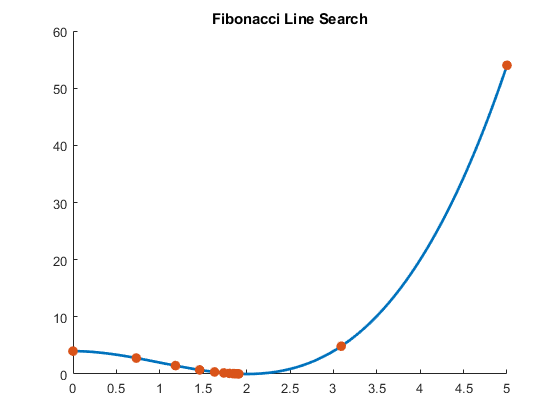

function x = plot_unimodal_method(G,f,df,ddf,testpts,startpt,a,b,res,ptitle)
    X = linspace(a,b,res);
    Y = f(X);
    
    x = G(f,df,ddf,startpt,a,b,20);

    
    figure; hold on;
    plot(X, Y, 'LineWidth', 2);
    plot(x, f(x), '.', 'MarkerFaceColor', 'auto', 'MarkerSize', 25);
    title(ptitle);
    hold off;
end

function x = fibonacci_search(f,~,~,~,a,b,N)
    % Generate Fibonacci numbers
    fib = [1 1];
    for i = 3:N+1
        fib = [fib fib(i-1)+fib(i-2)];
    end
    
    delta = [a b];
    d0 = delta(2) - delta(1);
    d = fib(N-1) / fib(N) * d0;
    
    x_m = delta(2) - d;
    x_p = delta(1) + d;
    x = [a b x_m x_p];
    
    fx_m = f(x_m);
    fx_p = f(x_p);

    for k = 2:N-1
        d = (fib(N-k) / fib(N-k+1)) * d;
        x_m = delta(2) - d;
        x_p = delta(1) + d;
        
        if(fx_m <= fx_p)
            delta = [delta(1) x_p];             
            fx_p = f(x_p);
            x = [x x_p];
        else
            delta = [x_m delta(2)];
            fx_m = f(x_m);
            x = [x x_m];
        end
    end
end